% --- Valeur par defaut pour que le simulink tourne
K = zeros(1, 4);
G = zeros(1, 1);
Kx = zeros(1, 4);
Ki = zeros(1, 1);
Kb = zeros(1, 1);

% -- Global parameters
y0 = [259; 5.2; 93.4; 259; 100.2; 95.4]; % Mesure initiale quand les moteurs sont à 0
dt = 1/30;

% --- Si données depuis simulink
data = out.logsout;
% --- Si préenregistré
%load("state_space.mat") 

% --- Recuperation des données
u = squeeze(getElement(data, "u").Values.Data)';
x = squeeze(getElement(data, "x").Values.Data);
y = squeeze(getElement(data, "y").Values.Data);

t  = getElement(data, "y").Values.Time';

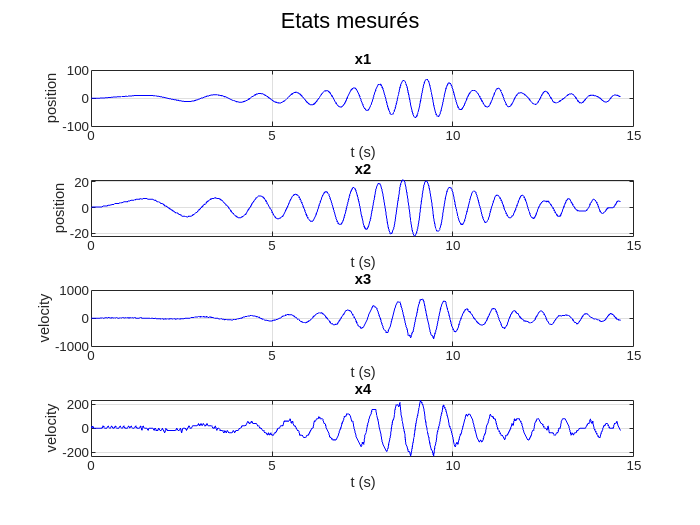

% --- State 
labels_x = {'position', 'position', 'velocity', 'velocity'};

figure;
for i = 1:4
    subplot(4, 1, i);
    plot(t, x(i, :), 'b');
    ylabel(labels_x{i});
    xlabel("t (s)")
    title(sprintf('x%d', i));
    grid on;
end
sgtitle('Etats mesurés');

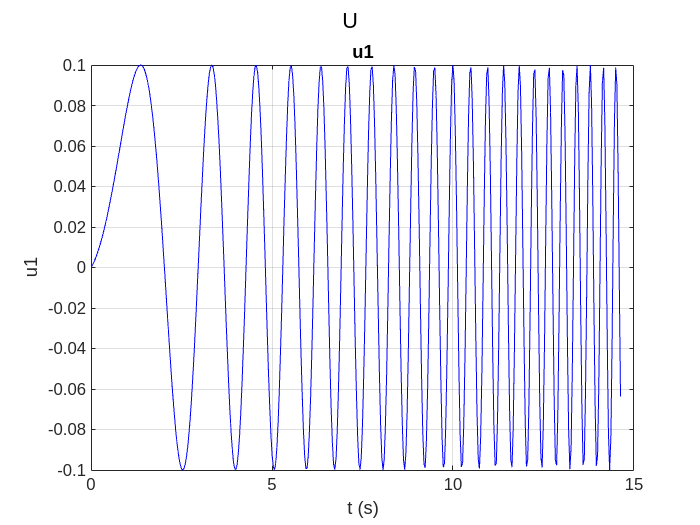

% --- U
labels_u = {'u1'};
figure;
for i = 1:1
    subplot(1, 1, 1);
    plot(t, u(i, :), 'b');
    ylabel(labels_u{i});
    xlabel("t (s)")
    title(sprintf('u%d', i));
    grid on;
end
sgtitle('U');

% --- Identification
x_curr = x(:, 1:end-1);
x_next = x(:, 2:end);  
u_curr = u(:, 1:end-1);

Z = [x_curr; u_curr];        
M = x_next * pinv(Z); 

% --- Extraction de A et B
nx = size(x, 1);
A  = M(:, 1:nx);
B  = M(:, nx+1:end);
C = [1 0];

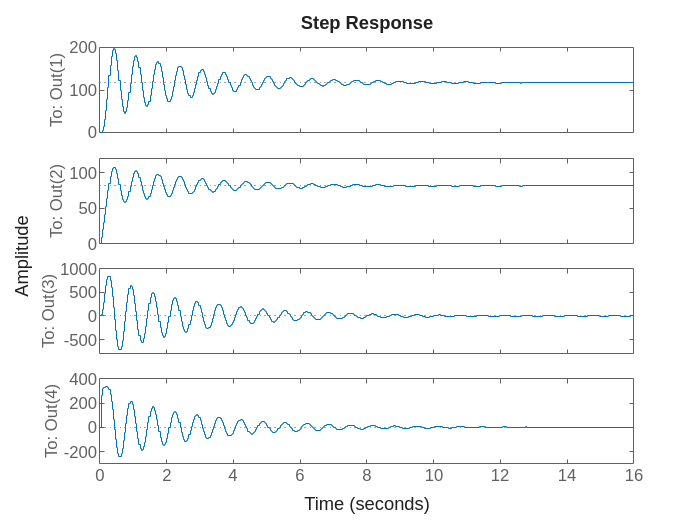

sys = ss(A, B, eye(4), 0, dt);
figure
step(sys)

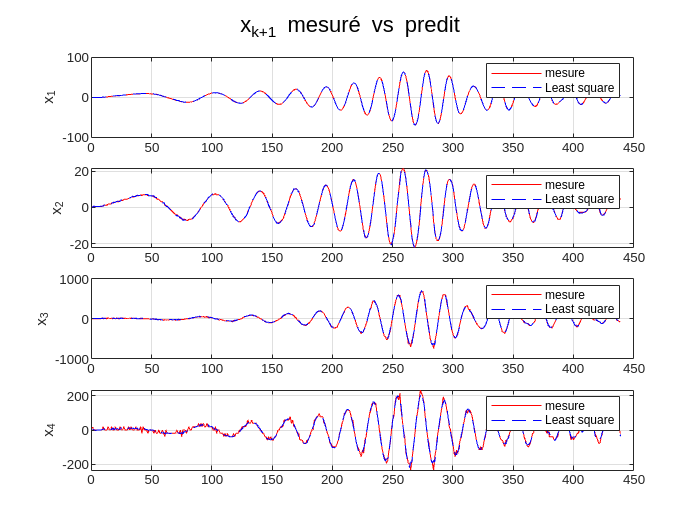

% --- Verification

% Prediction
x_next_est = A * x_curr + B * u_curr;
figure;
for i = 1:size(x, 1)
    subplot(size(x,1), 1, i);
    plot(x_next(i, :), 'r', 'DisplayName', 'mesure');
    hold on;
    plot(x_next_est(i, :), 'b--', 'DisplayName', 'Least square');
    ylabel(['x_' num2str(i)], 'Interpreter', 'tex');
    legend; grid on;
end
sgtitle('x_{k+1} mesuré vs predit', 'Interpreter', 'tex');

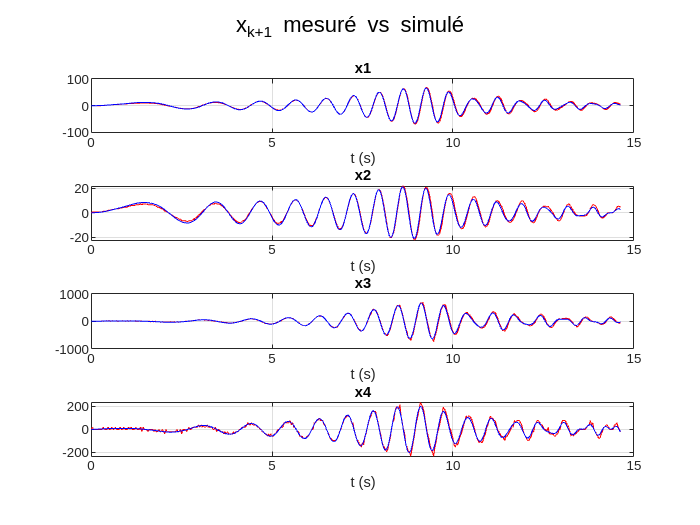



% Simulation
[ysim, tsim, xsim] = lsim(sys, u,t, x(:, 1));
figure;
%tn = t(1:end-1);
tn = t;
for i = 1:size(x, 1)
    subplot(size(x, 1), 1, i);
    plot(tn, x(i, :), 'r');
    hold on 
    plot(tsim, xsim(:, i), 'b');
    hold off
    xlabel("t (s)")
    title(sprintf('x%d', i));
    grid on;
end
sgtitle('x_{k+1} mesuré vs simulé', 'Interpreter', 'tex');

% --- Control 
damp(sys);

                                                                                    
         Pole             Magnitude     Damping       Frequency      Time Constant  
                                                    (rad/seconds)      (seconds)    
                                                                                    
  9.38e-01 + 3.09e-01i     9.88e-01     3.86e-02       9.54e+00         2.72e+00    
  9.38e-01 - 3.09e-01i     9.88e-01     3.86e-02       9.54e+00         2.72e+00    
  6.08e-01                 6.08e-01     1.00e+00       1.49e+01         6.69e-02    
  4.93e-01                 4.93e-01     1.00e+00       2.12e+01         4.71e-02    


wn1 = 9.48;
xi1 = 0.3;
wn2 = 13.8;
xi2 = 0.4;

vpc = [-xi1*wn1+j*wn1*sqrt(1-xi1^2), -xi1*wn1-j*wn1*sqrt(1-xi1^2)];
vpd = exp(vpc * dt);
vp = [vpd 0.608 0.493];

K = place(A, B, vp);
C_ctr = [1 0 0 0];
G = inv(C_ctr * inv(eye(nx) - A + B * K) * B);


% ---Avec Integrateur
Abar = [A zeros(size(A,1), 1); -C_ctr 1];
Bbar = [B; 0];

vpbar = [vp 0.99];
Kbar = place(Abar, Bbar, vpbar);
Kx = Kbar(:, 1:size(A, 1));
Ki = Kbar(:, size(A, 1)+1:size(A, 1)+1);
Kb = 10;